# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

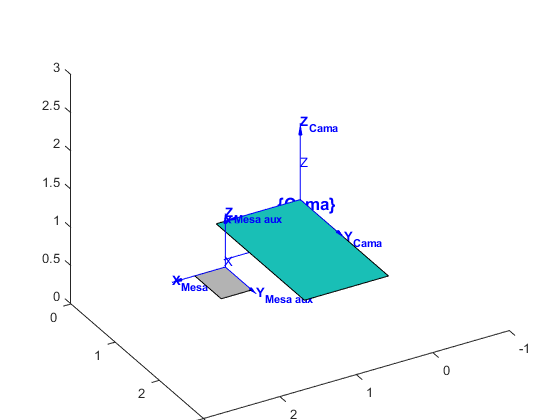

clear all

A= 1.1;
L = 2;

aux_A= 0.4;
aux_L = 0.6;

centro_cama = [0 0 0.5];
centro_aux = [1.5 0.9 0.5];

escalado = 0.1; % escala del cranio y tumor para que este acorde al tamaño del humano

FA = eye(4);
FB = eye(4);
yaw = 0; %eje z
roll = 0; % eje x
pitch = 0; % eje y

yaw_aux = 0; %eje z
roll_aux = 0; % eje x
pitch_aux = 0; % eje y

mat_aux = [ 0 0 0 1; aux_A 0 0 1; aux_A aux_L 0 1; 0 aux_L 0 1]';
mat_cama = [ 0 0 0 1; A 0 0 1; A L 0 1; 0 L 0 1]';

r = rpy2r(roll, pitch, yaw,'deg');
r = r2t(r);

r_aux = rpy2r(roll_aux, pitch_aux, yaw_aux,'deg');
r_aux = r2t(r_aux);

FA = transl(centro_cama)*r; %cama 
FB = transl(centro_aux)*r_aux; %mesa aux

mat_cama = transl(centro_cama)*r*mat_cama;
mat_cama = mat_cama(1:3,:);

mat_aux = transl(centro_aux)*r_aux*mat_aux;
mat_aux = mat_aux(1:3,:);

hold on
s= fill3(mat_cama(1,:), mat_cama(2,:), mat_cama(3,:), [1 1 1 1]);
set(s,'facealpha',1);

s2= fill3(mat_aux(1,:), mat_aux(2,:), mat_aux(3,:), [0.7 0.7 0.7]);
set(s2,'facealpha',1);

trplot(eye(4)); % mundo
trplot(FA, ... 
    'frame', 'Cama', ...
    'color', 'b',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
     'length',1,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);
trplot(FB, ... 
    'frame', 'Mesa aux', ...
    'color', 'b',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
     'length',0.7,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1);

axis([-1 3 0 3 0 3])

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

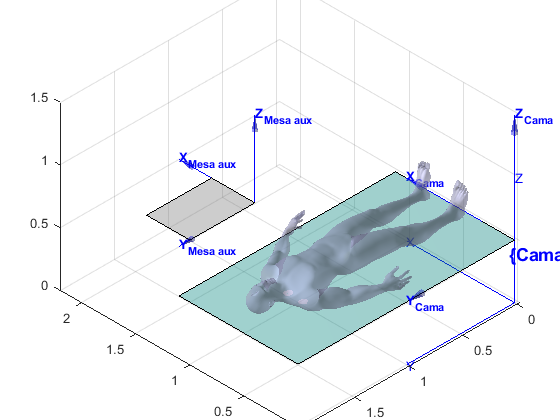

altura_human = 1.80;

load('SP_material/F_V_Human_Body.mat');
% Para redimencionar al cuerpo multiplicamos los vertices
max_y = max(V(:,2));

tamano = altura_human/max_y;

V = V*tamano;
% Buscamos la anchura después de hacer el escalado.
min_z_humano = min(V(:,3));

%centramos al humano en la mesa
centrado = altura_human/2;

V(:,4) = ones(size(V,1),1); % Añadir fila de 1 para poder trasladar
V = V'; % Transponer para hacer la multiplicacion
V = transl(A/2,-centrado+L/2,-min_z_humano)*V;
V = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*V;
V = V(1:3,:);
V = V';


stlPlot(V,F,'human')
alpha 0.4;
axis equal;

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

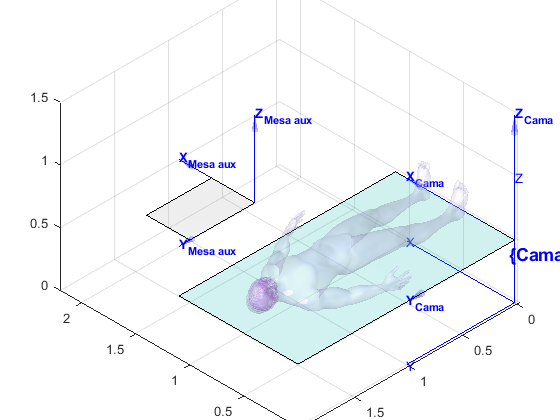

%fv = stlread('SP_material/Crani.stl');
load('Crani.mat');

% Para redimencionar al cuerpo multiplicamos los vertices
max_min_crani(1,2) = max(fv.vertices(:,2));
tamano_crani = escalado/max_min_crani(1,2);
fv.vertices = fv.vertices*tamano_crani;

max_min_crani(1,3) = max(fv.vertices(:,3)); % max z

% Buscamos la anchura después de hacer el escalado.
% para luego centrar la parte de arriba del craneo con la parte de arriba de la cabeza del humano

% añadimos el fiducial
fiducial_y = tamano_crani;  % calculamos la posición
fiducial_x = tamano_crani;

fv.vertices(:,4) = ones(size(fv.vertices,1),1); % Añadir fila de 1 para poder trasladar
fv.vertices = fv.vertices'; % Transponer para hacer la multiplicacion

fv.vertices = transl(A/2,L/2,-min_z_humano)*trotx(-90, 'deg')*fv.vertices; %rotamos y centramos a la mesa
fv.vertices = transl(0,centrado-max_min_crani(1,3),0)*fv.vertices; % subimos para que este a la altura de la cabeza
fv.vertices = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*fv.vertices; % trasladamos a la posicion de la mesa

fv.vertices = fv.vertices(1:3,:);
fv.vertices = fv.vertices';

patch(fv,'FaceColor',       [0.7 0.5 0.9], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);
     
camlight('headlight');
material('shiny');

alpha 0.2;


max_min_crani(1,1) = max(fv.vertices(:,1)); %max x
max_min_crani(2,1) = min(fv.vertices(:,1)); % min x

max_min_crani(1,2) = max(fv.vertices(:,2)); % max y
max_min_crani(2,2) = min(fv.vertices(:,2)); % min y

max_min_crani(1,3) = max(fv.vertices(:,3)); % max z
max_min_crani(2,3) = min(fv.vertices(:,3)); % min z

centro_crani = [(max_min_crani(1,1)+max_min_crani(2,1))/2,(max_min_crani(1,2)+max_min_crani(2,2))/2,(max_min_crani(1,3)+max_min_crani(2,3))/2];

%axis('image');
%view([-135 35]);

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

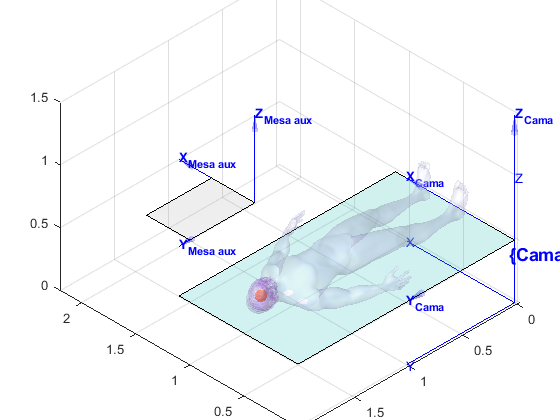

load('tumor_points.mat');

% Para redimencionar al cuerpo multiplicamos los vertices
max_min_tumor(1,2) = max(tumor(:,2));
tamano_tumor = (escalado)/max_min_tumor(1,2);
tumor = tumor*tamano_tumor;

max_min_tumor(1,1) = max(tumor(:,1)); %max x
max_min_tumor(2,1) = min(tumor(:,1)); % min x

max_min_tumor(1,2) = max(tumor(:,2)); % max y
max_min_tumor(2,2) = min(tumor(:,2)); % min y

max_min_tumor(1,3) = max(tumor(:,3)); % max z
max_min_tumor(2,3) = min(tumor(:,3)); % min z

centro_tumor = [(max_min_tumor(1,1)+max_min_tumor(2,1))/2,(max_min_tumor(1,2)+max_min_tumor(2,2))/2,(max_min_tumor(1,3)+max_min_tumor(2,3))/2];

tumor(:,4) = ones(size(tumor,1),1); % Añadir fila de 1 para poder trasladar
tumor = tumor'; % Transponer para hacer la multiplicacion
tumor = transl(-centro_tumor(1),-centro_tumor(2),-centro_tumor(3))*tumor; % centramos al eje de coordenadas

% Esto será un punto en todo el centro del cranio
x = centro_crani(1);
y = centro_crani(2);
z = centro_crani(3);
scatter3(x,y,z,'filled');

% el tumor hay que girarlo primero 180grados en Y y 90 en x. Para que este bien
%tumor = transl(A/2,L/2,-max_min_tumor(2,3))*trotx(90,'deg')*troty(-180,'deg')*tumor; %rotamos y centramos a la mesa
tumor = trotx(90,'deg')*troty(-180,'deg')*tumor; %rotamos y centramos a la mesa
%tumor = transl(0,centrado-max_min_tumor(1,3),-min_z_humano)*tumor; % subimos para que este a la altura de la cabeza
tumor = transl(centro_crani(1),centro_crani(2),centro_crani(3))*tumor; % subimos para que este a la altura de la cabeza
x = tumor(1,:);
y = tumor(2,:);
z = tumor(3,:);
scatter3(x,y,z,'filled');




% axis([-.1 0.2 -0.1 0.2 -0.1 0.2]);

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

%% put your code Here

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

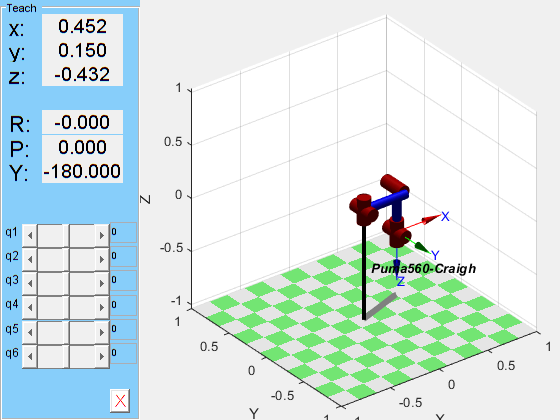

clear;mdl_puma560_Craigh
p560Craigh.plot(qz)
p560Craigh.teach

EE=p560Craigh.fkine(qz)

No appropriate method, property, or field 'Fine' for class 'SerialLink'.

p560Craigh.tool = SE3(centro_cama(1),centro_cama(2)+1.5, centro_cama(z)+2)
p560Craigh.base = SE3(0, 0, 30*0.0254)
p560Craigh

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

10.- Prepare a script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts her**e.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts her**e.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here